旋转曲面

生成一条平面曲线

x = [-5:.2:5]

x =    -5.0000   -4.8000   -4.6000   -4.4000   -4.2000   -4.0000   -3.8000   -3.6000   -3.4000   -3.2000   -3.0000   -2.8000   -2.6000   -2.4000   -2.2000   -2.0000   -1.8000   -1.6000   -1.4000   -1.2000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000


y = x.^2/4 + 4

y =    10.2500    9.7600    9.2900    8.8400    8.4100    8.0000    7.6100    7.2400    6.8900    6.5600    6.2500    5.9600    5.6900    5.4400    5.2100    5.0000    4.8100    4.6400    4.4900    4.3600    4.2500    4.1600    4.0900    4.0400    4.0100    4.0000    4.0100    4.0400    4.0900    4.1600    4.2500    4.3600    4.4900    4.6400    4.8100    5.0000    5.2100    5.4400    5.6900    5.9600    6.2500    6.5600    6.8900    7.2400    7.6100    8.0000    8.4100    8.8400    9.2900    9.7600


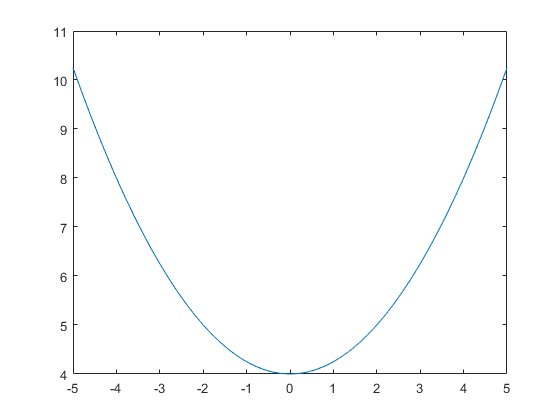

plot(x,y)

生成一条三维曲线

生成一条绕z轴的三维曲面C

z1 = [-5:.2:5]

z1 =    -5.0000   -4.8000   -4.6000   -4.4000   -4.2000   -4.0000   -3.8000   -3.6000   -3.4000   -3.2000   -3.0000   -2.8000   -2.6000   -2.4000   -2.2000   -2.0000   -1.8000   -1.6000   -1.4000   -1.2000   -1.0000   -0.8000   -0.6000   -0.4000   -0.2000         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000


y1 = z1.^2/4 + 4

y1 =    10.2500    9.7600    9.2900    8.8400    8.4100    8.0000    7.6100    7.2400    6.8900    6.5600    6.2500    5.9600    5.6900    5.4400    5.2100    5.0000    4.8100    4.6400    4.4900    4.3600    4.2500    4.1600    4.0900    4.0400    4.0100    4.0000    4.0100    4.0400    4.0900    4.1600    4.2500    4.3600    4.4900    4.6400    4.8100    5.0000    5.2100    5.4400    5.6900    5.9600    6.2500    6.5600    6.8900    7.2400    7.6100    8.0000    8.4100    8.8400    9.2900    9.7600


x1 = z1.^2/4 + 4 - y1

x1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x1,y1,z1)
hold on

生成一条z轴

y2 = z1 - z1

y2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


x2 = z1 - z1

x2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot3(x2,y2,z1)


生成一条曲线C绕z轴的旋转曲面

更具 y = z^2/4  y = sqrt(x^2+y^2） 带入可得 z^2/4 = sqrt(x^2+y^2)

化简得  z = sqrt(4*sqrt(x3.^2+y3.^2)) 或者 z = -sqrt(4*sqrt(x3.^2+y3.^2))

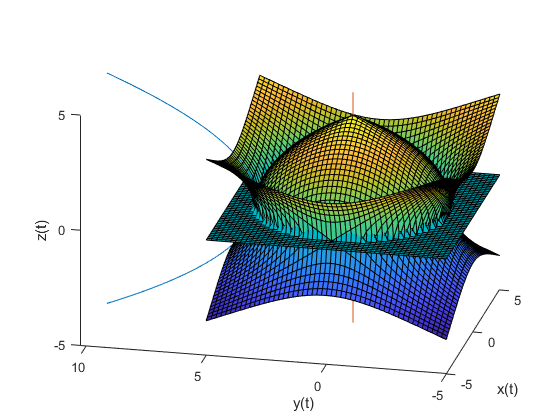

[x3,y3] = meshgrid(-5:.2:5);

surf(x3, y3, real(sqrt(4*sqrt(x3.^2+y3.^2)-16)))
surf(x3, y3, -real(sqrt(4*sqrt(x3.^2+y3.^2)-16)))
surf(x3, y3, B)



xlabel('x(t)')
ylabel('y(t)')
zlabel('z(t)')
axis equal 